clc,clear;
syms a b;
c=[a b]';
A=[250, 2400, 4900, 5150, 5500, 6892, 6457, 7579, 7785, 9834, 10045, 11532, 11603, 17478, 14820, 14402, 24821, 22200, 25000, 22000, 26152, 29862]

A =          250        2400        4900        5150        5500        6892        6457        7579        7785        9834       10045       11532       11603       17478       14820       14402       24821       22200       25000       22000       26152       29862


%A=[89677,99215,109655,120333,135823,159878,182321,209407,246619,300670];
%A=[250	2650	7550	12700	18200	25092	31549	39128	46913	56747	66792	78324	89927	107405	122225	136627	161448	183648	208648	230648	256800	286662]
B=cumsum(A)  %原始数据累加

B =          250        2650        7550       12700       18200       25092       31549       39128       46913       56747       66792       78324       89927      107405      122225      136627      161448      183648      208648      230648      256800      286662


n=length(A);
for i=1:(n-1)
    C(i)=(B(i)+B(i+1))/2; %生成累加矩阵
end
%计算待定参数的值
D=A;D(1)=[];
D=D';
E=[-C;ones(1,n-1)];
c=inv(E*E')*E*D;
c=c';
a=c(1);b=c(2);
%预测后续数据
F=[];F(1)=A(1);
for i=2:(n+75)  %只推测后10个数据，可以从此修改
    F(i)=(A(1)-b/a)/exp(a*(i-1))+b/a;
end
G=[];G(1)=A(1);
for i=2:(n+75)  %只推测后10个数据，可以从此修改
    G(i)=F(i)-F(i-1);  %得到预测出来的数据
end
t1=1:22;
t2=1:97;  %多10组数据
G

G =    1.0e+05 *

    0.0025    0.0459    0.0505    0.0556    0.0612    0.0674    0.0742    0.0817    0.0900    0.0991    0.1091    0.1201    0.1323    0.1457    0.1604    0.1766    0.1945    0.2141    0.2358    0.2596    0.2859    0.3148    0.3466    0.3816    0.4202    0.4627    0.5095    0.5610    0.6177    0.6802    0.7489    0.8246    0.9080    0.9998    1.1009    1.2122    1.3348    1.4697    1.6183    1.7819    1.9621    2.1604    2.3789    2.6194    2.8842    3.1758    3.4969    3.8504    4.2397    4.6683


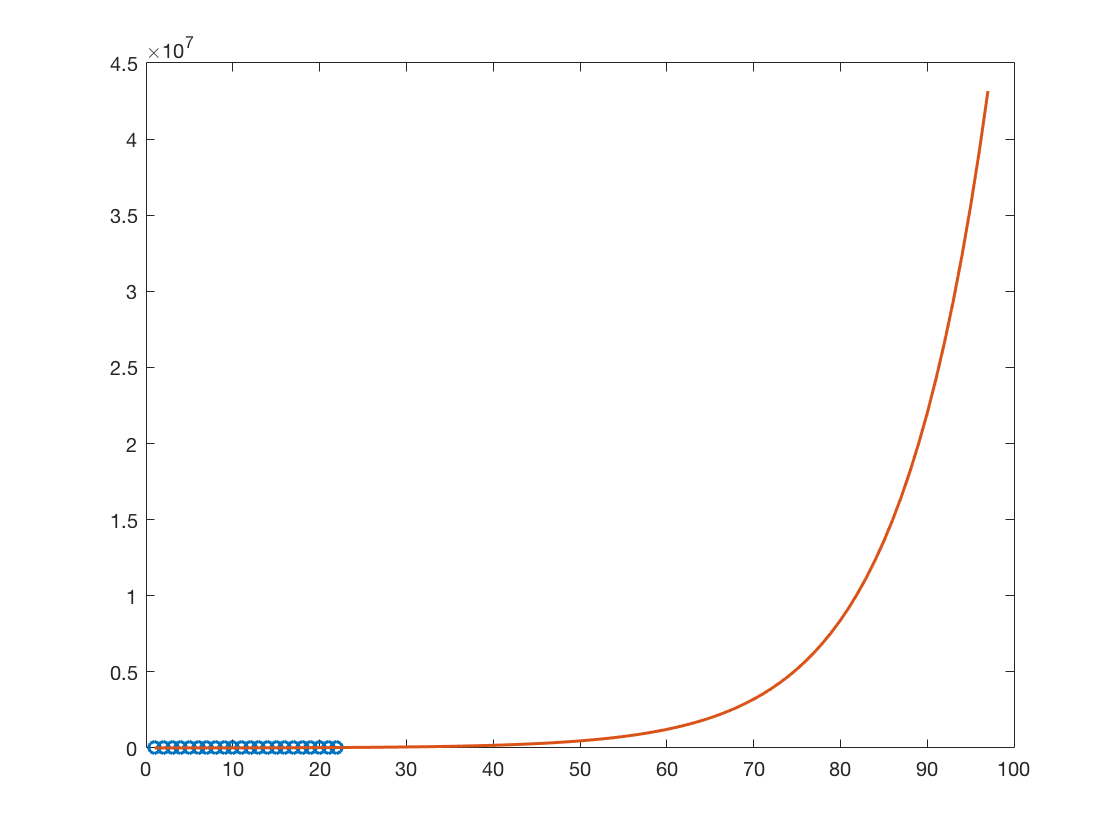

h=plot(t1,A,'o',t2,G,'-'); %原始数据与预测数据的比较
set(h,'LineWidth',1.5);    

AP = G(1, 1:n)

AP =    1.0e+04 *

    0.0250    0.4586    0.5050    0.5560    0.6123    0.6742    0.7423    0.8174    0.9000    0.9910    1.0912    1.2015    1.3230    1.4567    1.6040    1.7662    1.9447    2.1413    2.3578    2.5962    2.8587    3.1477


%BP = cumsum(AP)
%res = B - BP;
%plot(t1,res, 'o')
%axis([0,25,-20000,20000])

maxAP=max(abs(AP));
ap=AP./maxAP;
maxA=max(abs(A));
a=A./maxA;
delta=abs(a-ap)

delta =     0.0004    0.0653    0.0037    0.0042    0.0103    0.0166    0.0196    0.0059    0.0252    0.0145    0.0103    0.0045    0.0317    0.1225    0.0133    0.0788    0.2134    0.0631    0.0881    0.0881    0.0324         0


conn = (min(delta) + 0.5463*max(delta))./(delta + 0.5 * max(delta))

conn =     1.0882    0.6776    1.0564    1.0513    0.9962    0.9453    0.9230    1.0356    0.8837    0.9620    0.9966    1.0486    0.8421    0.5086    0.9715    0.6284    0.3642    0.6864    0.5984    0.5985    0.8380    1.0926


r = mean(conn)

r = 0.8542

sumBEV = cumsum(G)

sumBEV =    1.0e+06 *

    0.0003    0.0048    0.0099    0.0154    0.0216    0.0283    0.0357    0.0439    0.0529    0.0628    0.0737    0.0857    0.0990    0.1135    0.1296    0.1472    0.1667    0.1881    0.2117    0.2376    0.2662    0.2977    0.3324    0.3705    0.4126    0.4588    0.5098    0.5659    0.6276    0.6957    0.7706    0.8530    0.9438    1.0438    1.1539    1.2751    1.4086    1.5556    1.7174    1.8956    2.0918    2.3078    2.5457    2.8076    3.0961    3.4136    3.7633    4.1484    4.5723    5.0392


sumBEV = sumBEV([3:4:97])

sumBEV =    1.0e+08 *

    0.0001    0.0004    0.0007    0.0013    0.0021    0.0033    0.0051    0.0077    0.0115    0.0172    0.0255    0.0376    0.0555    0.0818    0.1205    0.1774    0.2609    0.3838    0.5644    0.8298    1.2200    1.7936    2.6368    3.8762


sumBEV = sumBEV ./ 1000;
length(sumBEV)

ans = 24

%Malthusian model of population growth
syms y t;
syms k positive;
y=simplify(dsolve('Dy=k*y','y(1970)=203211926'));
kk=vpa(solve(subs(y,t,1990)==248710000),10)

$$kk = 0.01010190771$$

%Logistic growth
syms P t;
syms r M positive;
model=simplify(dsolve('DP=r*(M-P)*P'));
model=model(3)

$$model = \frac{M}{{\mathrm{e}}^{-M\,\left(C_{5}+r\,t\right)}+1}$$

latex(model)

ans = '\frac{M}{{\mathrm{e}}^{-M\,\left(C_{5}+r\,t\right)}+1}'

time_points=1990:2017;
observe_value=[193057.38
192313.83
194427.35
198041.34
201801.92
205427.21
210441.25
211580.03
215496
220461.06
225821.24
235331.38
234624.14
236760.03
243010.55
247421.12
250844.64
254403.08
255917.66
254212.61
250070.05
253108.39
253639.39
255876.82
260350.94
263610.22
268799.08
269980.]';
test_M=[269980:50:280000];
SS=[];
PP=[];
for mm=test_M
    yy=log(observe_value./(double(mm)-observe_value));
    [P,S]=polyfit(time_points,yy,1);
    S=S.normr;
    SS=[SS;S];
    PP=[PP;P];
end
[M_,I]=min(SS);
P_=PP(I,:);
M_=test_M(I);
r_=P_(1)/M_;
tstar = -P_(2)/P_(1);
C5_=-tstar*r_;
syms C5;
model=simplify(subs(model,[M C5 r],[M_ C5_ r_]));
latex(vpa(model,2))

ans = '\frac{2.8\,{10}^5}{6.5\,{10}^{74}\,{\mathrm{e}}^{-0.087\,t}+1.0}'

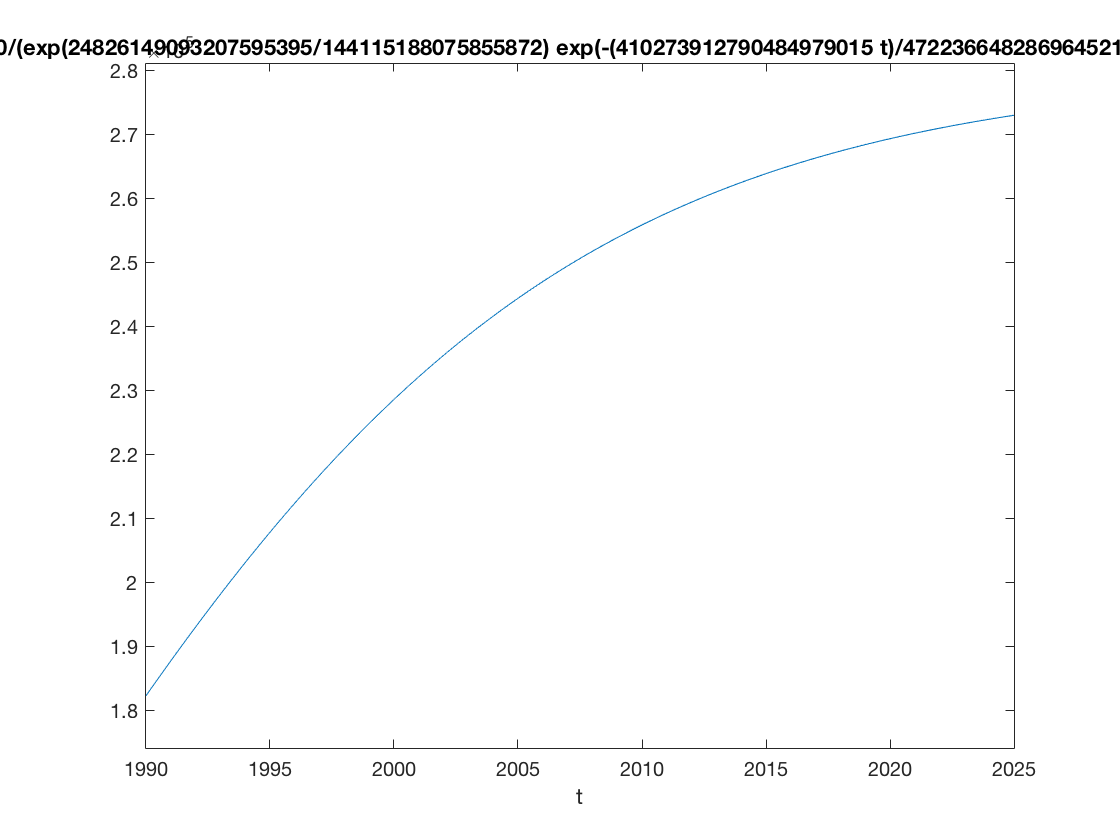

ezplot(model,[1990,2025])
hold on;

%plot(time_points, observe_value, 'og')

sells=[193057.38
192313.83
194427.35
198041.34
201801.92
205427.21
210441.25
211580.03
215496
220461.06
225821.24
235331.38
234624.14
236760.03
243010.55
247421.12
250844.64
254403.08
255917.66
254212.61
250070.05
253108.39
253639.39
255876.82
260350.94
263610.22
268799.08
269980.];

t1=1990:2017;

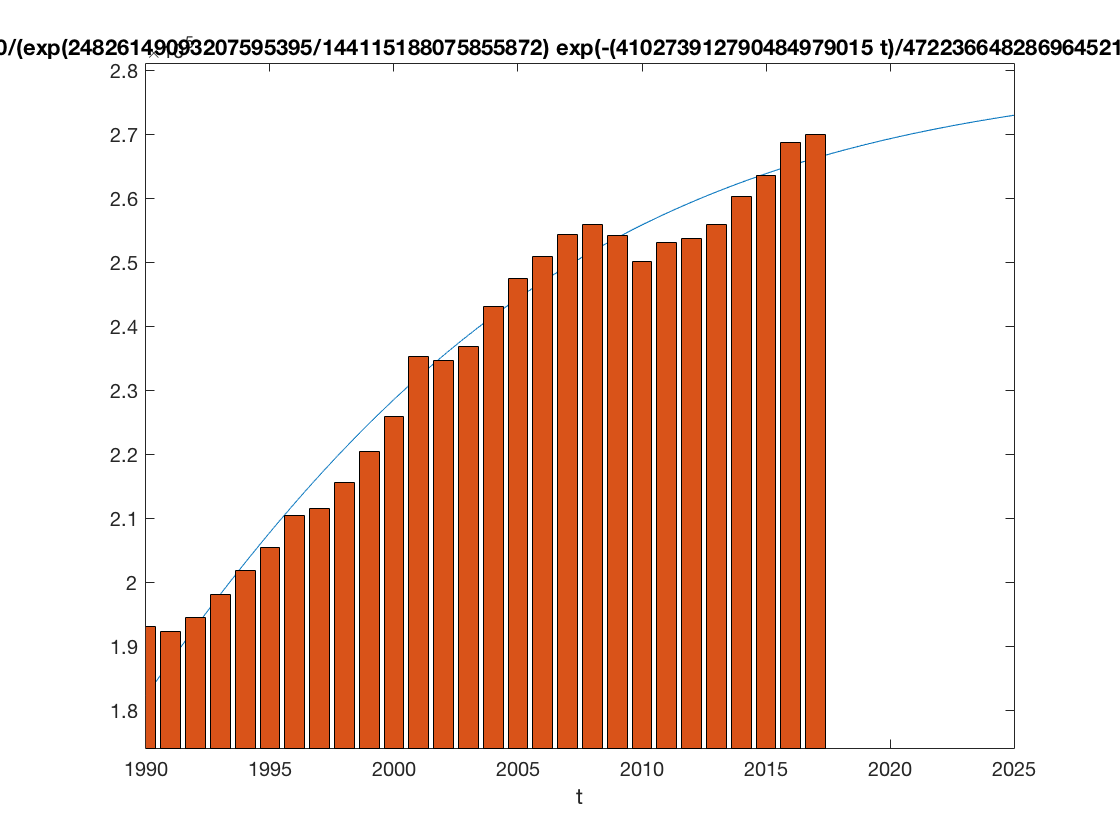

bar(t1,sells)
hold off;

h=ezplot(model,[1990,2025])

h =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×434 double]
              YData: [1×434 double]
              ZData: [1×0 double]

  Show all properties


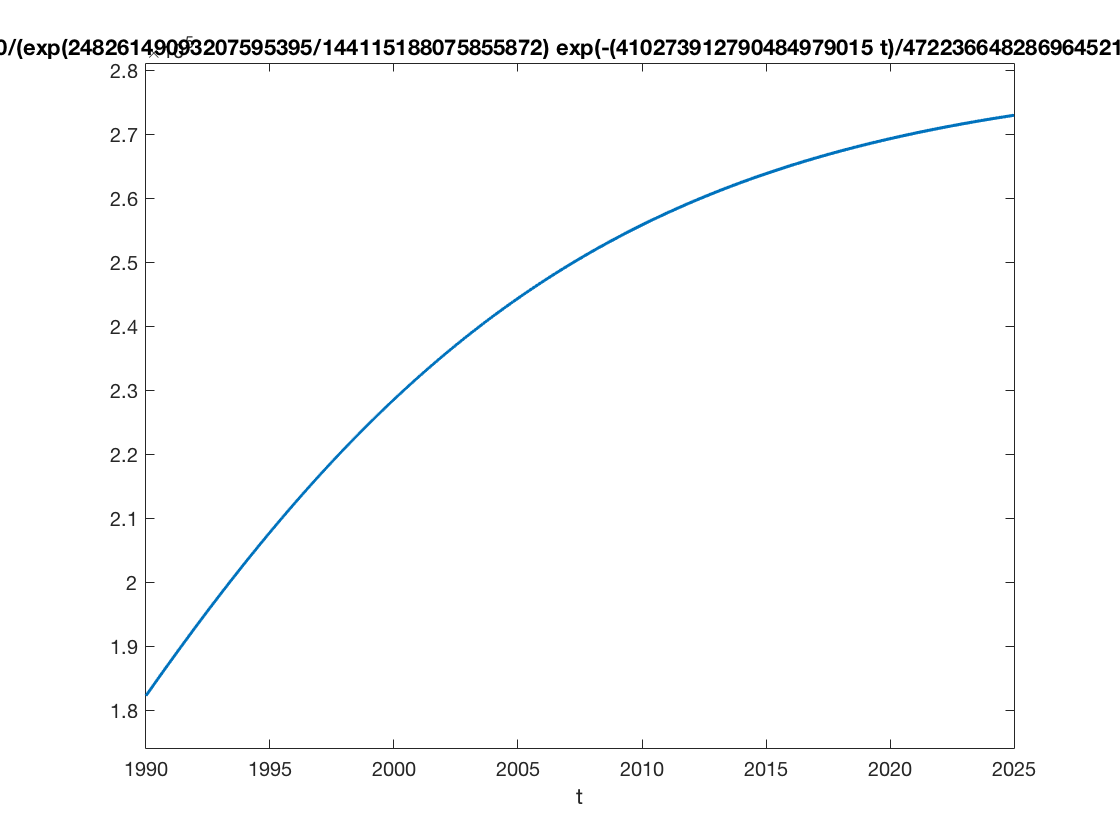

set(h,'LineWidth',1.5); 
hold off;

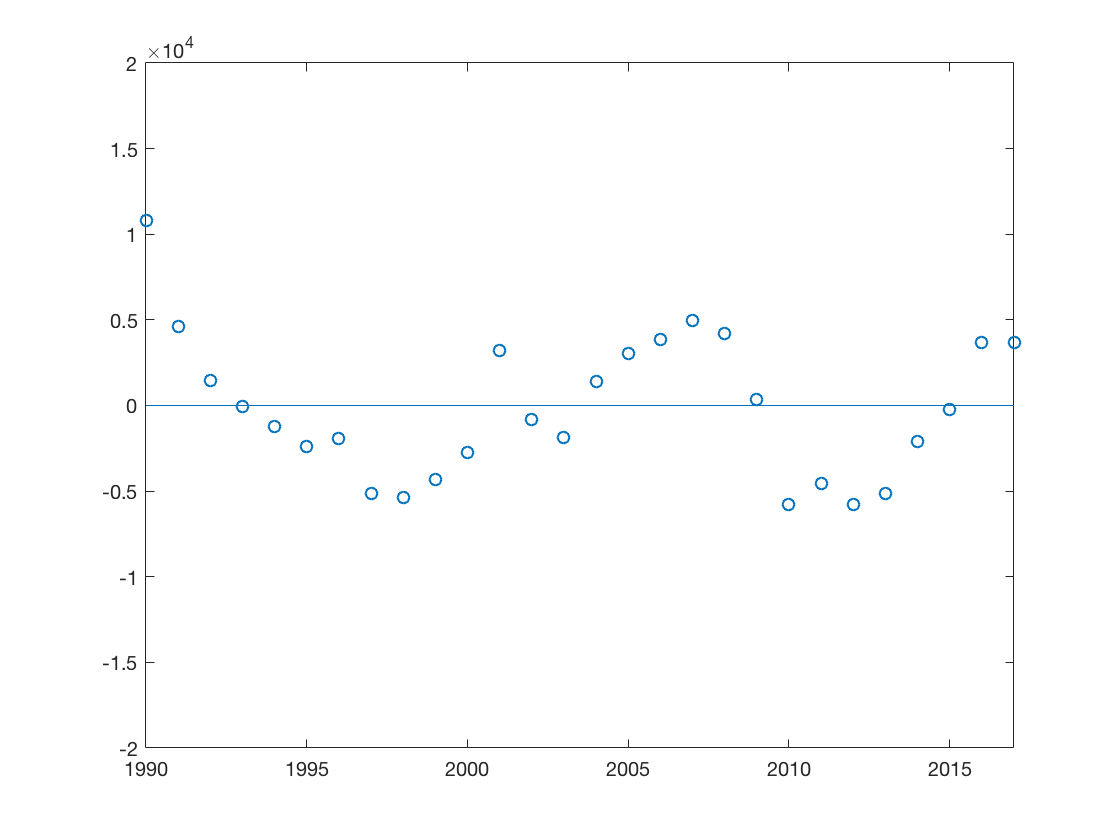

ypred = vpa(subs(model,t,[1990:2017]),2);
res = observe_value - ypred;
plot([1990:2017],res, 'o')
axis([1990,2017,-20000,20000])
line([1990,2017],[0,0])

h =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×434 double]
              YData: [1×434 double]
              ZData: [1×0 double]

  Show all properties


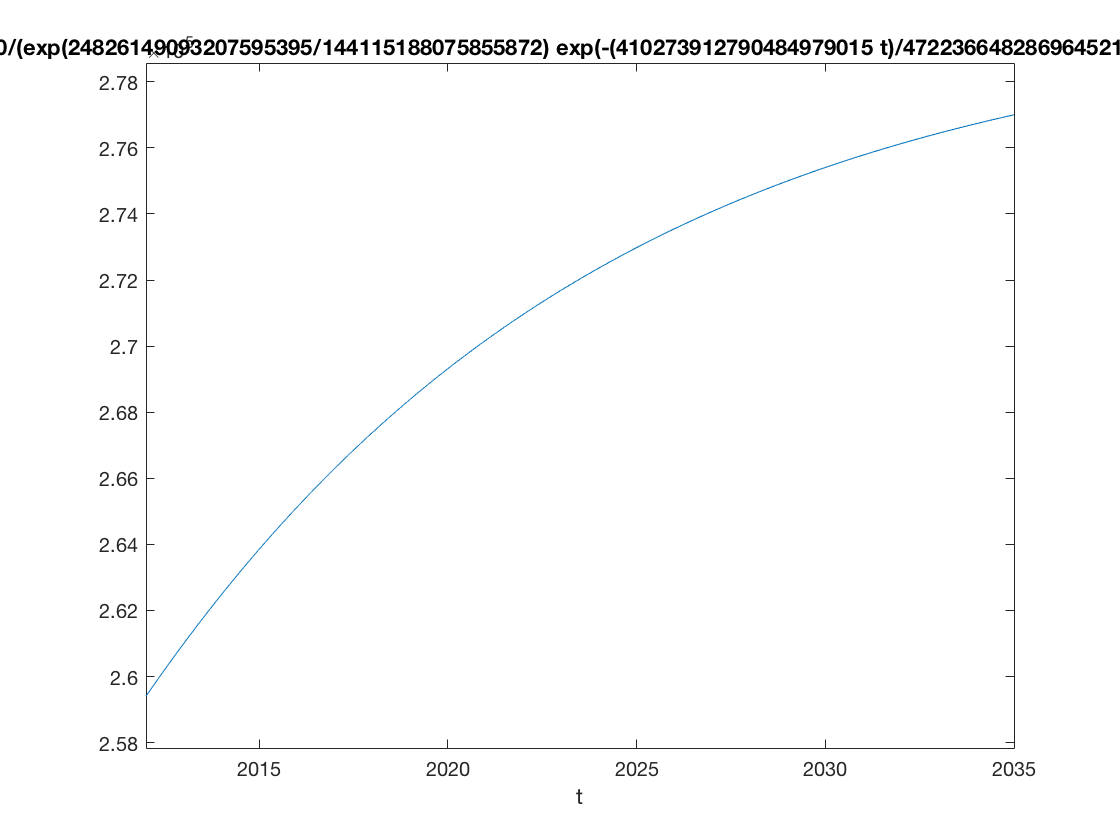

h=ezplot(model,[2012:2035])

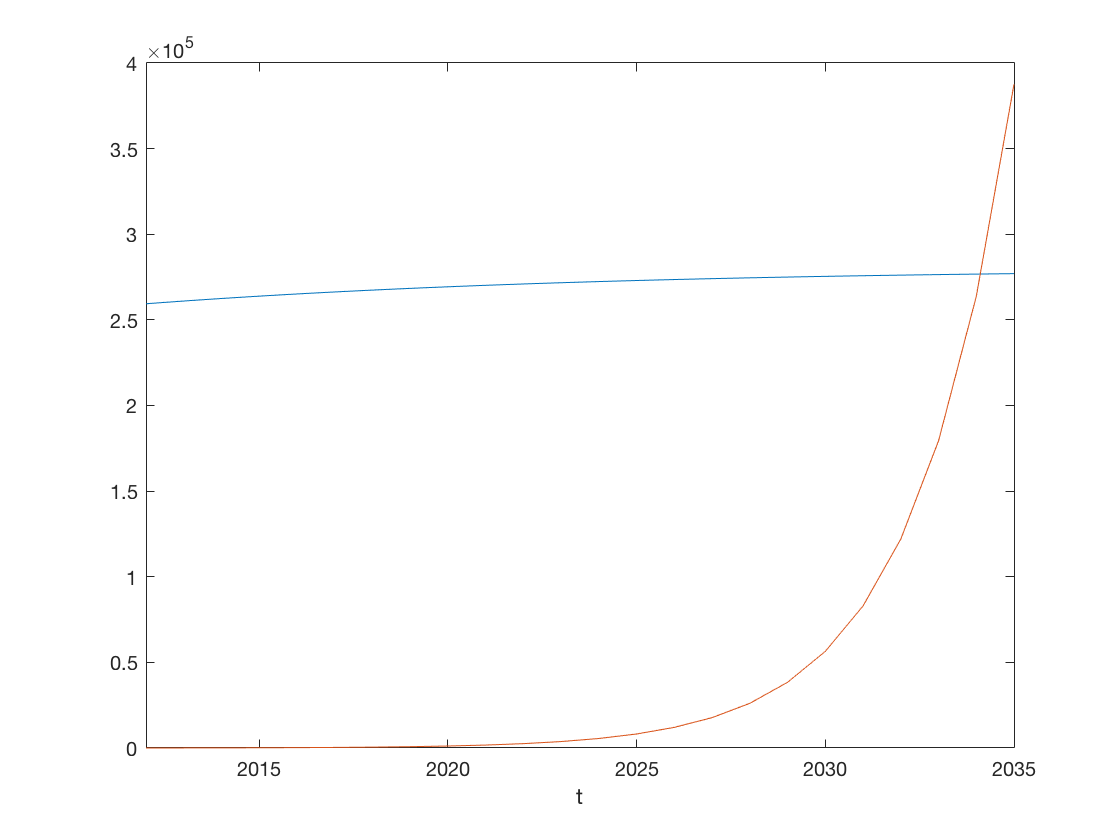

title ('')
hold on;
plot([2012:2035],sumBEV)
axis([2012,2035,0,4*10e4])
hold off;